# Ejercicios raíces

The bisection method is used to find roots—that is, solutions to equations of the form f (x) = 0. Suppose we want to find the solution to an equation of the form f(x) = 5. How would we use this method to do that?

fx = @(x) cos(x); % lets assume this is our function
fx(0)

ans =      1


fx = @(x) fx(x) - 5; % we have to edit the function so that f(x) = 0
fx(0)

ans =     -4


Suppose we are using the bisection method to estimate a root. After 6 steps, starting with initial interval [1, 4], regardless of the equation being considered, the error between the approximation and an actual root will be at most how much?

% At most 0.046875, since we have 4-1 = 3, which is our interval's length,
% our six step would be 2^6, which means our error would be 3 / 2^6 which
% equals 0.046875

Lets compute $x=\sqrt{2}$ using bisection.

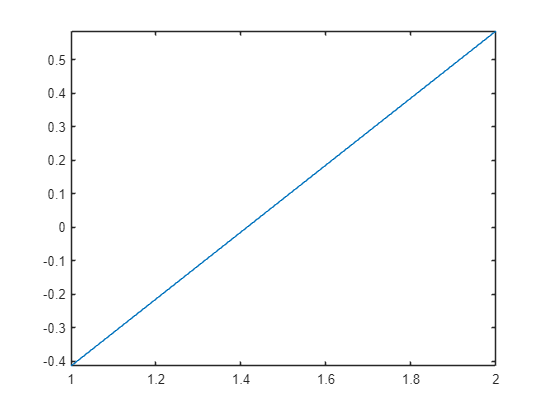

fx = @(x) x - sqrt(2);
fplot(fx, [1 2])

[root, iterations] = bisection(fx, 1.4, 1.5);
fprintf('Biseccion - raiz: %1.6f - iteraciones: %d', root, iterations)

Biseccion - raiz: 1.414214 - iteraciones: 49

Usando el algoritmo de bisección, calcula todas las soluciones de la ecuación


$$x+4\cos \left(x\right)=0$$


fx = @(x) x + 4*cos(x)

fx = function_handle with value:
    @(x)x+4*cos(x)


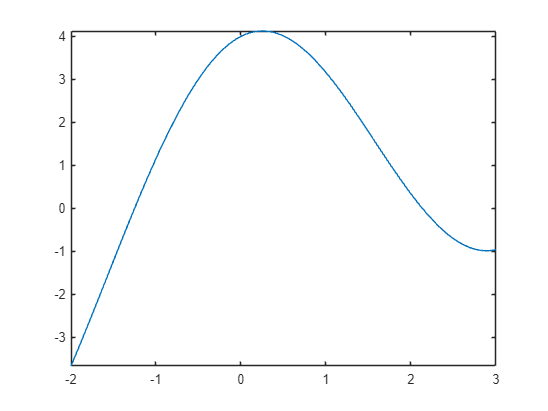

fplot(fx,[-2 3])


[root, iterations] = bisection(fx, -2, -1);
fprintf('Biseccion - raiz: %1.6f - iteraciones: %d', root, iterations)

Biseccion - raiz: -1.252353 - iteraciones: 53


[root, iterations] = bisection(fx, 2, 3);
fprintf('Biseccion - raiz: %1.6f - iteraciones: %d', root, iterations)

Biseccion - raiz: 2.133332 - iteraciones: 52

Usando el método de falsa posición, encuentra las primeras tres raíces no triviliales ($\not= 0,1$) de la función 

$f\left(x\right)=\sin \left(x-x^3 \right)$. Como la función es impar, solo estudia el caso de las soluciones positivas. 

Grafica la función en el intervalo [-3 3]. Debes definir la función de manera que no existan warnings al graficar.

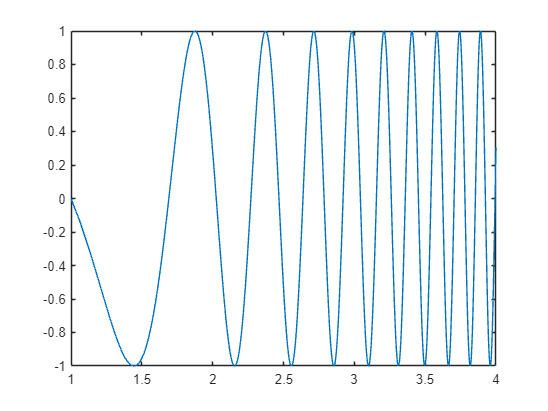

fx = @(x) sin(x - x.^3);
fplot(fx, [1 4])

Encuentra la primera raíz no trivial positiva.

[root, iterations] = falsePosition(fx, 1.5, 1.8);
fprintf('Interpolacion lineal - raiz: %1.6f - iteraciones: %d', root, iterations)

Interpolacion lineal - raiz: 1.690632 - iteraciones: 10

Encuentra la segunda raíz no trivial positiva.

[root, iterations] = falsePosition(fx, 1.8, 2.2);
fprintf('Interpolacion lineal - raiz: %1.6f - iteraciones: %d', root, iterations)

Interpolacion lineal - raiz: 2.025391 - iteraciones: 10

Encuentra la tercera raíz no trivial positiva.

[root, iterations] = falsePosition(fx, 2.3, 2.5);
fprintf('Interpolacion lineal - raiz: %1.6f - iteraciones: %d', root, iterations)

Interpolacion lineal - raiz: 2.269841 - iteraciones: 9

5.7 Determine the roots of f (x) = −12 − 21*x + 18*x^2 − 2.75*x^3 graphically. In addition, determine the first root of the function with bisection (linear interpolation and Newton-Raphson)

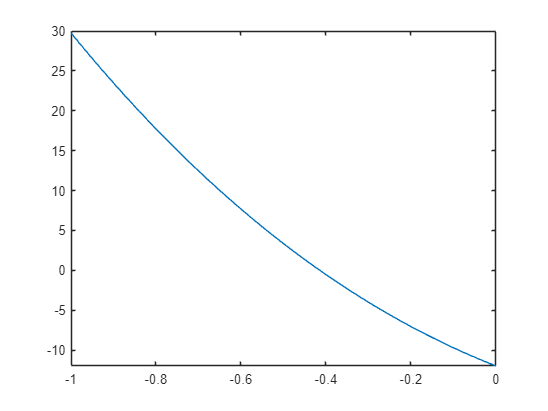

fx = @(x) -12 - 21*x + 18*x.^2 - 2.75*x.^3;
fplot(fx, [-1 0])

This plot indicates that roots are located at about –0.4, 2.25 and 4.7.

[root, iterations] = newtonRaphson(fx, -0.6);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.414689 - iteraciones: 5

5.8 Locate the first nontrivial root of sin(x) = x^2 where x is in radians. Use a graphical technique and a numerical algorithm..

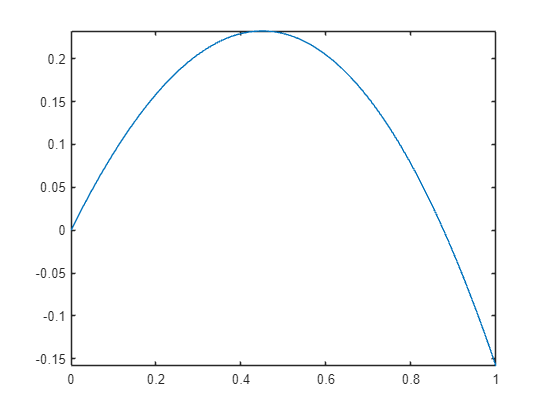

fx = @(x) sin(x) - x.^2;
fplot(fx,[0 1])


[root, iterations] = newtonRaphson(fx, 0.8);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.876726 - iteraciones: 5

5.9 Determine the positive real root of ln(x^2) = 0.7 (a) graphically, (b) using a numerical method, with initial guess in xl = 0.5 and xu = 2

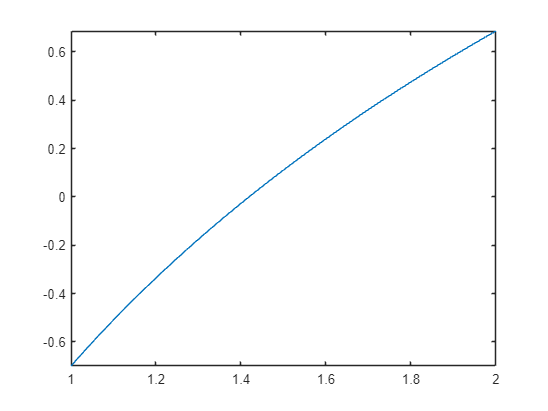

fx = @(x) log(x.^2) - 0.7;
fplot(fx, [1 2])


[root, iterations] =  brent(fx, 0.5, 2);
fprintf('Brent - raiz: %1.6f - iteraciones: %d', root, iterations)

Brent - raiz: 1.419068 - iteraciones: 6

Find the value of $x$ if $x^3 =20$ using a) Newton-Raphson, b) secant.

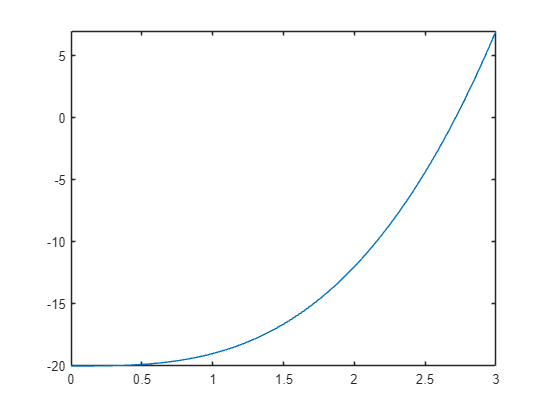

fx = @(x) x.^3 - 20;
fplot(fx, [0 3])


[root, iterations] = newtonRaphson(fx, 2);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 2.714418 - iteraciones: 5


[root, iterations] = secant(fx, 2, 3);
fprintf('Secante - raiz: %1.6f - iteraciones: %d', root, iterations)

Secante - raiz: 2.714418 - iteraciones: 7

Calcula, utilizando el algoritmo de Newton-Raphson, el radio $r$ de una esfera cuyo volumen ($\frac{4}{3}\pi r^3$) sea $\pi$ (centímetros cúbicos).

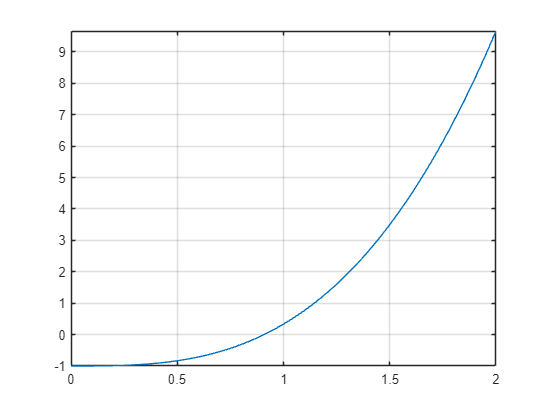

g = @(r) (4/3)*r.^3 - 1;
fplot(g, [0,2])
grid on

[root, iterations] = newtonRaphson(g, 1);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.908560 - iteraciones: 4

Usa el el algoritmo de Newton-Raphson para encontrar, la primera raíz positiva de la ecuación


$$f\left(x\right)=e^{{-x}^2 } -\cos \left(2x\right)-1=0$$


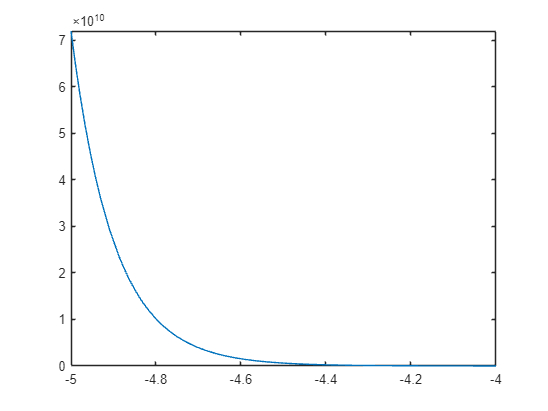

fx = @(x) exp(x.^2) - cos(2*x) - 1;
fplot(fx, [-5 -4])


[root, iterations] = newtonRaphson(fx, -4.6);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.579838 - iteraciones: 26

¿Por qué no podemos usar $x_0 =0$?

% porque newton raphson utiliza la derivada en un punto para calcular la
% raiz, y la derivada no existe en 0 por lo que nos arroja NaN

https://en.wikipedia.org/wiki/Legendre_polynomials

The Legendre polynomial of the sixth order is given by


$$P_6 \left(x\right)=\frac{1}{48}\left(693x^6 -945x^4 +315x^2 -15\right)$$


Find the zeros of $P_6 \left(x\right)$ using Newton’s method. (Note: All the zeros of the Legendre polynomial are less than one in magnitude and, for polynomials of an even order, are symmetric about the origin.)

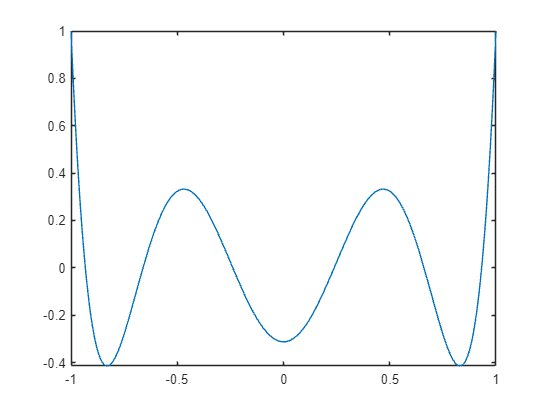

fx = @(x) 1/48*(693*x.^6 - 945*x.^4 + 315*x.^2 - 15);
fplot(fx, [-1 1])


[root, iterations] = newtonRaphson(fx, -1);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.932470 - iteraciones: 6


[root, iterations] = newtonRaphson(fx, -0.7);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.661209 - iteraciones: 4


[root, iterations] = newtonRaphson(fx, -0.3);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.238619 - iteraciones: 4


[root, iterations] = newtonRaphson(fx, 0.1);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.238619 - iteraciones: 5


[root, iterations] = newtonRaphson(fx, 0.6);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.661209 - iteraciones: 5


[root, iterations] = newtonRaphson(fx, 0.9);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.932470 - iteraciones: 5


$$P_n \left(1\right)=1$$


$P_0 \left(x\right)=1$;    $P_1 \left(x\right)=x$

https://en.wikipedia.org/wiki/Chebyshev_polynomials

The Chebyshev polynomial of degree 6 is given by


$$T_6 \left(x\right)=32x^6 -48x^4 +18x^2 -1$$


Find the zeros of $T_6 \left(x\right)$ using Newton’s method. (Note: All the zeros of the Chebyshev polynomial are less than one in magnitude.)

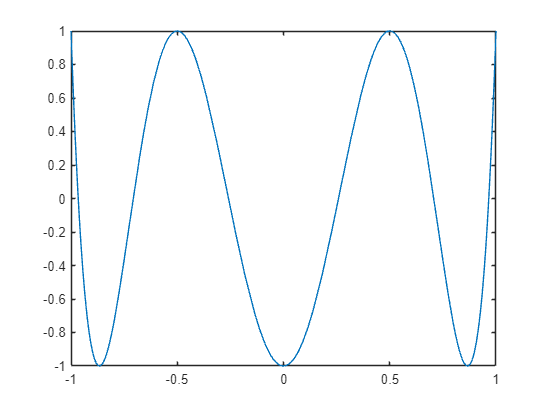

fx = @(x) 32*x.^6 - 48*x.^4 + 18*x.^2 - 1;
fplot(fx, [-1 1])


[root, iterations] = newtonRaphson(fx, -1);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.965926 - iteraciones: 5


[root, iterations] = newtonRaphson(fx, -0.7);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.707107 - iteraciones: 3


[root, iterations] = newtonRaphson(fx, -0.3);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -0.258819 - iteraciones: 4


[root, iterations] = newtonRaphson(fx, 0.1);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.258819 - iteraciones: 5


[root, iterations] = newtonRaphson(fx, 0.6);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.707107 - iteraciones: 5


[root, iterations] = newtonRaphson(fx, 0.9);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 0.965926 - iteraciones: 7


$$T_n \left(\cos \left(\theta \right)\right)=\cos \left(n\;\theta \right)$$



$$T_n \left(1\right)=1$$


$T_0 \left(x\right)=1$;    $T_1 \left(x\right)=x$;    $T_{n+1} \left(x\right)=2\;x\;T_n \left(x\right)-T_{n-1} \left(x\right)$

Calcula el punto de corte de las gráficas de$f\left(x\right)=\frac{1}{1+x^2 }$ y $g\left(x\right)=2x$, utilizando el algoritmo de Newton-Raphson.

f = @(x) 1./(1+x.^2);
g = @(x) 2*x;
fplot(f,[-2,2])
grid on
hold on
fplot(g,[-2,2])

fg = @(x) f(x) - g(x);
[x,i] = newtonRaphson(fg,0.4)

x =      4.238537990697833e-01


i =      3


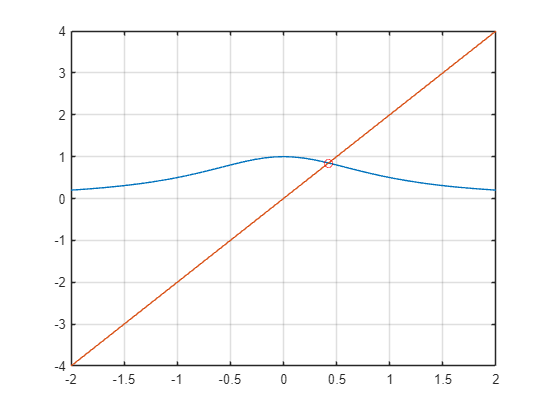

plot(x,f(x),'ro');
hold off

Encuentra el primer punto (menor valor de $x>0$) donde la hipérbola $y=\frac{1}{x}$ intersecta la curva $y=\cot \left(x\right)$.

f = @(x) 1./x;
g = @(x) cot(x);
fplot(f)
grid on
hold on
fplot(g)

fg = @(x) f(x) - g(x);
[x,i] = newtonRaphson(fg,0.5)

x =      3.862321857541752e-10


i =      3


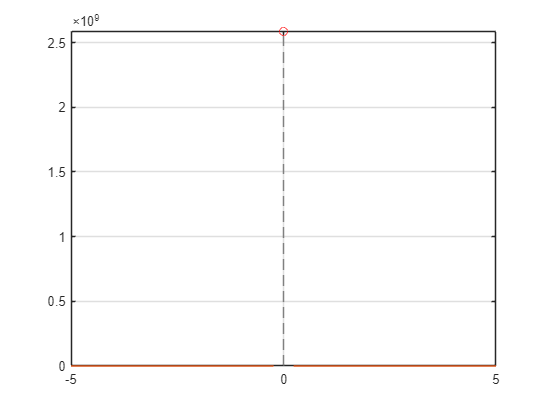

plot(x, f(x), 'ro');
hold off

#### Método de punto fijo

Suppose we have an equation $f\left(x\right)=0$, for which we have to find the solution. The equation can be expressed as $x=g\left(x\right)$. Choose $g\left(x\right)$ such that $\left|g^{\prime } \left(x\right)<1\right|$ at $x=x_0$ where $x_0$, is some initial guess. Then the iterative method is applied by successive approximations given by $x_{i+1} =g\left(x_i \right)$, that is, $x_1 =g\left(x_0 \right)$, $x_2 =g\left(x_1 \right)$ and so on.

Find the root of


$$f\left(x\right)=2x^3 -11\ldotp 7x^2 +17\ldotp 7x-5\;$$


located between 1.9 and 2 using fixed point iteration.

First, plot f(x) in [0,4].

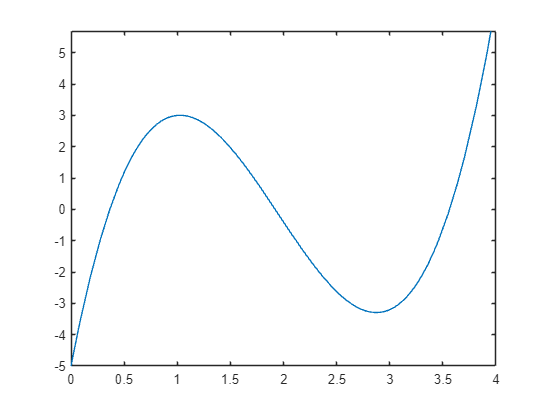

fx = @(x) 2*x.^3 - 11.7*x.^2 + 17.7*x - 5;
fplot(fx, [0 4])

Next, try

$g\left(x\right)=-\left(2x^3 -11\ldotp 7x^2 -5\right)$/17.7

using x0 = 1.9 and x0 = 2.

g = @(x) -(2*x.^3 - 11.7*x.^2 - 5)/17.7;

Fixed point iteration of g(x) fails to find the desired root. Why?

[root, iterations] = fixedPoint(g, 2);
fprintf('Punto fijo - raiz: %1.6f - iteraciones: %d', root, iterations)

Punto fijo - raiz: 3.563161 - iteraciones: 50


% fixed point has a tendency to not converge sometimes so the specific
% value must be far from it's f(x)

Use a better g(x) to find the desired root.

% no fucking idea

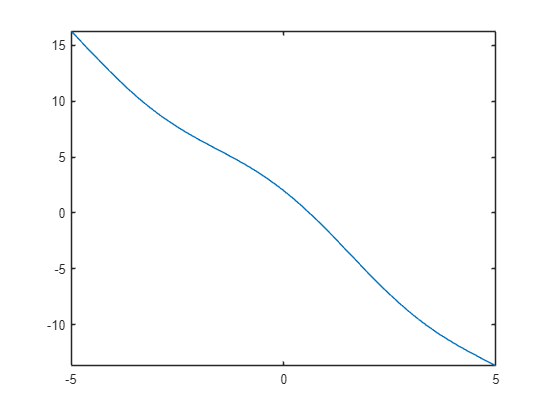

f = @(x) cos(x) - 3*x + 1;
fplot(f)


g = @(x) (cos(x) + 1)/3;
[root, iterations] = fixedPoint(g, -1);
fprintf('Punto fijo - raiz: %1.6f - iteraciones: %d', root, iterations)

Punto fijo - raiz: 0.607102 - iteraciones: 23

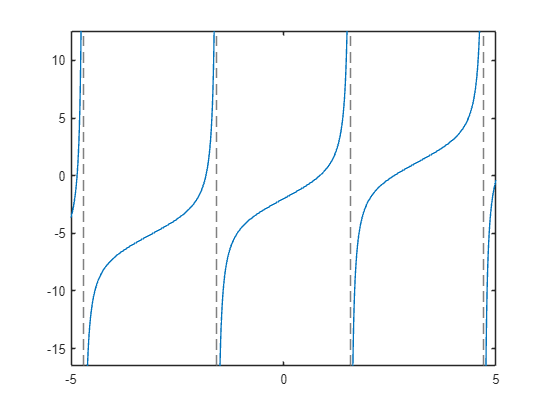

f = @(x) tan(x) + x - 2;
fplot(f)


g = @(x) 2 - atan(x);
[root, iterations] = fixedPoint(g, 0.8);
fprintf('Punto fijo - raiz: %1.6f - iteraciones: %d', root, iterations)

Punto fijo - raiz: 1.146470 - iteraciones: 43

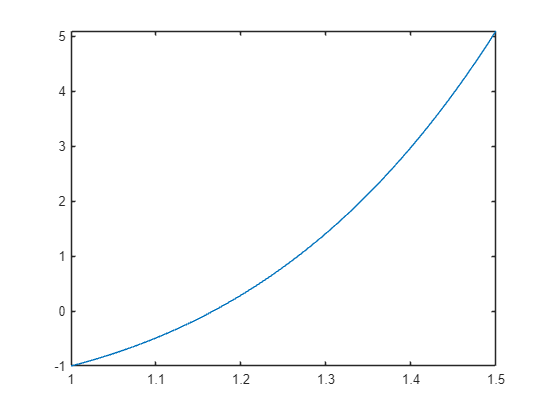

f = @(x) x.^5 - x - 1;
fplot(f, [1 1.5])


g = @(x) x.^5 - 1;
[root, iterations] = fixedPoint(g, 1.1);
fprintf('Punto fijo - raiz: %1.6f - iteraciones: %d', root, iterations)

Punto fijo - raiz: -Inf - iteraciones: 8

In the year 1225 Leonardo de Pisa estudió la ecuación


$$f\left(x\right)=x^3 +2x^2 +10x-20=0$$


y produjo x = 1.368808107. Nadie sabe qué método utilizó Leonardo para obtener este valor, pero es un resultado notable para su tiempo.

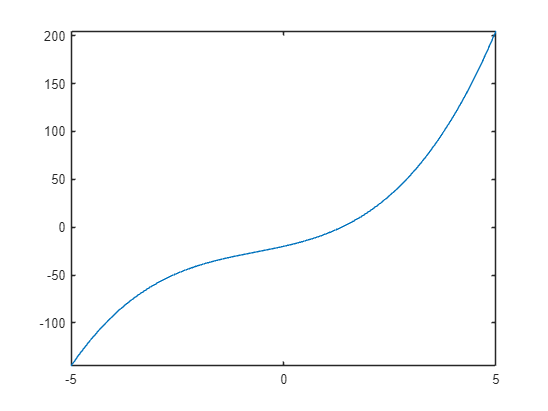

f = @(x) x.^3 + 2*x.^2 + 10*x - 20;
fplot(f)


[root, iterations] = newtonRaphson(f, 1.3);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 1.368808 - iteraciones: 4

Show that the function g(x) = sqrt(1 + x) has exactly one fixed point and calculate it.

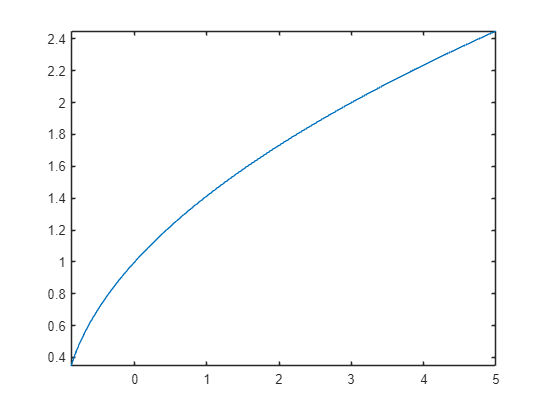

g = @(x) sqrt(x + 1);
fplot(g)


[root, iterations] = newtonRaphson(g, -1);
fprintf('Newton-Raphson - raiz: %1.6f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: -1.000000 - iteraciones: 1